# Тема 1: Основні положення проєктування інтелектуальних систем на базі нечіткої логіки

## Лекція 1: Нечіткі множини

1. Основи теорії множин та нечіткі множини

**Класична (чітка) множина** — це набір елементів, де кожен елемент або належить множині (1), або не належить (0).

**Нечітка множина** — це множина, де елементи можуть належати їй частково, з певним ступенем від 0 до 1.

**Приклад:**

- Чітка множина: "Високі люди — це люди вище 180 см" (або так, або ні)

- Нечітка множина: "Високі люди" — людина 175 см може бути "високою" зі ступенем 0.4, а 190 см — зі ступенем 0.9

**2. Функція приналежності**

**Функція приналежності μ(x)** показує, наскільки елемент x належить нечіткій множині. Значення від 0 до 1.

**Способи побудови функцій приналежності:**

- **Експертний метод** — експерти визначають форму функції

- **Статистичний метод** — на основі даних

- **Метод парних порівнянь** — порівнюють елементи попарно

**Типові форми функцій приналежності:**

- Трикутна (три точки: початок, пік, кінець)

- Трапецієподібна (плоска вершина)

- Гаусова (дзвоноподібна)

- Сигмоїдна (S-подібна)

**3. Аналітичний опис функцій**

**Трикутна функція:**

`μ(x) = 0, якщо x ≤ a`

`μ(x) = (x-a)/(b-a), якщо a < x ≤ b`

`μ(x) = (c-x)/(c-b), якщо b < x ≤ c`

`μ(x) = 0, якщо x > c`

**Гаусова функція:**

`μ(x) = exp(-(x-c)²/(2σ²))`

**4. Операції над нечіткими множинами**

**Об'єднання (АБО):** μ(A∪B) = max(μ(A), μ(B))

**Перетин (І):** μ(A∩B) = min(μ(A), μ(B))

**Доповнення (НЕ):** μ(Ā) = 1 - μ(A)

**5. Трикутні норми (T-норми та T-конорми)**

**T-норма** (узагальнення операції "І"):

- min(a,b) — мінімум

- a·b — добуток

**T-конорма** (узагальнення операції "АБО"):

- max(a,b) — максимум

- a+b-a·b — алгебраїчна сума

**6. Нечіткі відношення**

Описують зв'язки між елементами двох множин. Наприклад, "x набагато більше за y".

**Нечітка композиція** — поєднання кількох відношень для отримання нового.**Лекція 2: Проєктування інтелектуальних систем****1. Двійкова логіка**

**Висловлювання** — твердження, що має значення "істина" або "хибність".

**Предикат** — висловлювання зі змінними: P(x) = "x > 5"

**Логічні операції:** І (AND), АБО (OR), НЕ (NOT)

**2. Продукційні системи**

Системи на основі правил типу "ЯКЩО-ТО":

`ЯКЩО (температура висока) ТО (увімкнути кондиціонер)`

**3. Лінгвістичні змінні**

Змінні, що приймають словесні значення:

- Змінна: "Температура"

- Значення: "холодна", "нормальна", "тепла", "гаряча"

Кожне значення описується функцією приналежності.**4. Нечіткі правила**

`ЯКЩО (температура ТЕПЛА) І (вологість ВИСОКА) `

`ТО (комфорт НИЗЬКИЙ)`

Тут "ТЕПЛА", "ВИСОКА", "НИЗЬКИЙ" — нечіткі терми.**5. Нечітка імплікація**

Способи реалізації зв'язку "ЯКЩО-ТО":

- **Мамдані:** min(μ(A), μ(B))

- **Ларсен:** μ(A) · μ(B)

- **Цукамото:** для монотонних функцій

**6. Нечіткий висновок (алгоритм Мамдані)**

**Кроки:**

- **Фазифікація** — перетворення чітких вхідних даних у нечіткі (визначення ступенів приналежності)

- **Агрегування** — обчислення ступеня виконання кожного правила (min для І, max для АБО)

- **Активізація** — обрізання функцій приналежності висновків

- **Акумуляція** — об'єднання всіх висновків (max)

- **Дефазифікація** — перетворення нечіткого результату в чітке число

**7. Методи дефазифікації**

**Центр ваги (найпопуларніший):**

`x* = Σ(x·μ(x)) / Σμ(x)`

**Центр максимумів** — середнє значення точок з максимальною приналежністю

**Перший максимум** — найменше x з максимальною μ(x)**8. База правил**

**Вимоги:**

- **Повнота** — правила покривають весь діапазон вхідних значень

- **Несуперечність** — немає конфліктуючих правил

- **Безперервність** — плавні переходи між висновками

**Табличне подання:**

`| Температура | Вологість | → | Швидкість вентилятора |`

`|-------------|-----------|---|------------------------|`

`| Холодна     | Низька    | → | Дуже мала             |`

`| Тепла       | Середня   | → | Середня               |`

`| Гаряча      | Висока    | → | Максимальна           |`

**9. Нечітка система як універсальний апроксиматор**

Нечіткі системи можуть наближати будь-яку неперервну функцію з будь-якою точністю (теорема про універсальну апроксимацію).

**10. Нечітка динамічна система**

Система, де виходи залежать від поточних і попередніх станів:

`y(t) = f(x(t), x(t-1), y(t-1))`

Використовується для керування процесами, що змінюються в часі (робототехніка, автопілоти).

## Робота в MATLAB

Основні команди:

`% Створення нечіткої системи`

`fis = mamfis('Name', 'MySystem');`

`% Додавання вхідної змінної`

`fis = addInput(fis, [0 100], 'Name', 'temperature');`

`% Додавання функції приналежності`

`fis = addMF(fis, 'temperature', 'trimf', [0 25 50], 'Name', 'cold');`

`% Додавання вихідної змінної`

`fis = addOutput(fis, [0 100], 'Name', 'fan_speed');`

`% Додавання правила (ЯКЩО temp=cold ТО fan=low)`

`rule = "If temperature is cold then fan_speed is low";`

`fis = addRule(fis, rule);`

`% Обчислення результату`

`output = evalfis(fis, 30);`

`% Візуалізація`

`plotmf(fis, 'input', 1);  % Графік функцій приналежності`

**Fuzzy Logic Toolbox** — інструмент з графічним інтерфейсом для розробки нечітких систем у MATLAB.

**Підсумок:** Нечітка логіка дозволяє працювати з неточними, лінгвістичними даними і приймати рішення подібно до людського мислення. Вона ідеальна для задач, де складно формалізувати чіткі правила.

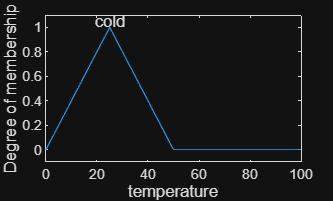

% Створення нечіткої системи
fis = mamfis('Name', 'MySystem');

% Додавання вхідної змінної
fis = addInput(fis, [0 100], 'Name', 'temperature');

% Додавання функції приналежності для ВХОДУ
fis = addMF(fis, 'temperature', 'trimf', [0 25 50], 'Name', 'cold');

% Додавання вихідної змінної
fis = addOutput(fis, [0 100], 'Name', 'fan_speed');

% ⚠️ ВАЖЛИВО: Додавання функції приналежності для ВИХОДУ
fis = addMF(fis, 'fan_speed', 'trimf', [0 25 50], 'Name', 'low');

% Додавання правила (тепер 'low' визначено для виходу)
rule = "If temperature is cold then fan_speed is low";
fis = addRule(fis, rule);

% Обчислення результату
output = evalfis(fis, 30);

% Візуалізація
plotmf(fis, 'input', 1);   % Графік функцій приналежності входу

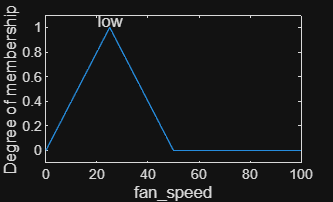

plotmf(fis, 'output', 1);  % Графік функцій приналежності виходу